# Cinemática con Matlab y Simulink

# Manual y Ejemplos Clase Cin

Dificultad: Normal (Básico)

clear all
close all


## Introducción

- El objetivo de la clase $Cin()$ es poder realizar un simulador de robot usando las herramientas **Multi-Body** de Simulink y **Rigid-Body** de Matlab. 

- Los métodos principales de la clase **Cin** son los movimientos típicos de todo lenguaje para programación de robot: $MoveAbsJ()$ (movimiento por coordenadas articulares), $MoveJ()$ (movimientos por coordenadas cartesianas), $MoveL()$ (movimiento en linea) y $MoveC()$ (movimiento en arco).

- Se parte de un modelo de robot definido en **Multi-Body** y su equivalente en **Rigid-Body** definido a partir del primero.

- A ambos modelos se les pueden añadir todo tipo de herramientas y objetos de trabajo. Sin embargo, la simulación de movimientos es más continua en Simulink, por lo que se va a usar básicamente **Multi-Body** para la simulación. 

- En este entorno se puede definir la velocidad de simulación y se va a poder grabar los movimientos realizados para posteriormente reproducirlos.

- El modelo equivalente de **Rigid-Body** es necesario para poder obtener las cinemáticas inversas y directas del modelo, ya que **Multi-Body** solo simula.

- Se ha diseñado un **HMI** (interface hombre-máquina) **appRastreador** basado en la herramienta **appdesigner** de matlab, que usando la clase **Cin**, mueve al robot en coordenadas cartesianas.

## Abrir clase Cin para Rigid-Body y Multi-Body

- Si se introducen como argumentos el objeto **Rigid-Body** y el fichero Simulink de **Multi-Body**, las salidas por pantalla se convierten en simulaciones a la velocidad deseada.

- El objeto **Rigid-Body** puede constar solo del robot, ya que no se va a visualizar, solo se va a usar para la obtención de la cinemática directa e inversa.

- En el fichero **Multi-Body** se pueden añadir las herramientas que se deseen y los objetos de trabajo.

deg= pi/180;
Estacion= 'C09S1_Estacion_irb120';

% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,6);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot [[x,y,z]mm,[Rz,Ry,Rx]rad]
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];

% Tool load y wobj Se genera una variable estructura de nombre tool1

% Herramienta/carga del robot
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza.Tcp([[0,0,70]*1e-3, [0,0,0]*deg]);
Pinza.Color([0.4,0,0.4,0.7]);

% Herramienta/Carga del robot
Carga= Pieza('Lapiz');
Carga.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);

% Objeto de trabajo del robot
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Objeto de trabajo
Tab= Pieza('Tablero');
Tab.Base([[0, 200, 100]*1e-3, [0, 0, 30]*deg]);
Tab.Color([0.2, 0.5, 0.1, 0.7])

% Icono fijo
% Mesa inclinada. Sus puntos están en una posición indeterminada respecto
% del origen. Es preciso usar la regla de los tres puntos para fijarlos
MesInc= Pieza('MesaInclinada');
MesInc.Base([[0, 0, 0]*1e-3, [0, 0, 0]*deg]);
% Ejes de la mesa por 3 puntos
% Puntos para definir los ejes de la mesa
x1= [0.4000, 0.1330, 0];
x2= [0.1500, -0.3000, 0];
y1= [0.7232, -0.0536, 0.1000];
MesInc.Tcp(Prod(x1,x2,y1));

MesInc.Color([0.3, 0.8, 0.2, 0.7]);


% Pieza('Botella', 'Botella');
% h= Hmat;
% h.Rad;
% Hbotella= h.t([45,0,45]*1e-3)*h.Rx(-90*deg);
% Botella.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
% Botella.Color([0,0.3,0.8,0.7]);


% Objeto de trabajo del robot
Cil= Pieza('Cilindro');
Cil.Base([[0, 300, 900]*1e-3, [0, 90, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);



--------------------
Robot: (10 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        Body10      

% Abrir fichero simulink
open_system(Estacion)

% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails
% Para recordar a que body pertenece las herramientas y cargas deseadas
% Es preciso mirarlo dentro de la estructura
TcpPinza= 'Body09';
TcpCarga= 'Body10';
% Abrir fichero simulink
open_system(Estacion)

### Diagrama Simulink Multi-Body

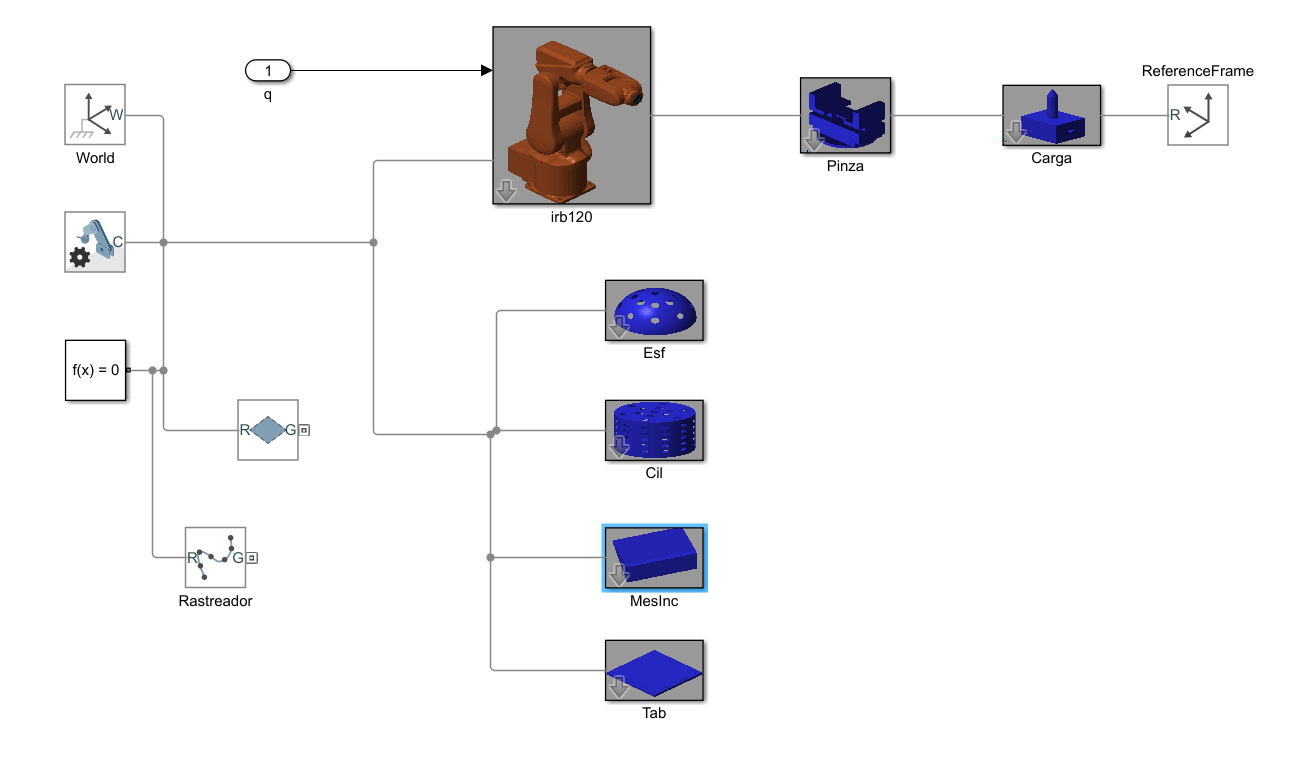

## Objeto $Cin()$ del sistema

% Se debe definir el rigid-body asociado a la estación, la estación simulink
% la herramienta deseada (última por defecto) y el valor de los ejes
% iniciales q0= [0,0,0,0,0,0] por defecto
q0= zeros(1,6);

Herramienta: Body10
Simulación. Ts= 0.100 m/s


q0_= zeros(1,6);

rob= Cin(robot, Estacion, TcpCarga, q0);


### Simulación con Cin

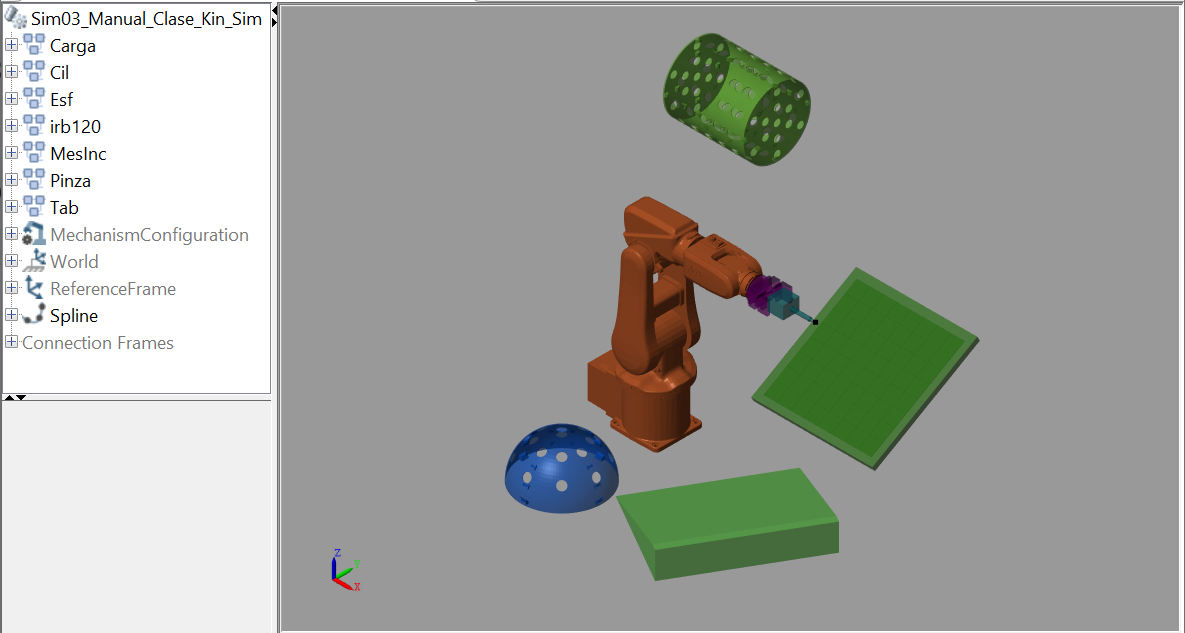

## Métodos de Rigid-Body

### 
$$Tool()$$


- Si se trabaja con **Multi-Body** y el objeto **Rigid-Body** asociado, esta función es útil para cambiar de herramienta, o entre carga y herramienta.

rob.Tool(TcpCarga)
rob.Show

## Métodos de Visualización y Velocidad de simulación

### 
$$Show( [joint], [pose])$$


- Sin argumentos, muestra el robot en la posición actual.

- Con el argumento *joint* muestra el robot a la posición articular dada y cambia la posición interna del robot.

- Rastreo de la posición del TCP: El argumento *pose, *matriz ($nPts\times 6$) del tipo $[x,y,z,r_z,r_y,r_x]$, dibuja los puntos dados interpolados en Simulink. Los métodos de movimiento lo emplean para rastrear el TCP del robot.

rob.Show

No hay record


### 
$$Rec(value)$$


- Graba todos los movimientos y tiempos de simulación para una futura reproducción general. 

- Sin argumentos resetea la información grabada y empieza a grabar. 

- Con $value=1$ empieza a grabar respetando los movimientos en memoria

- Con $value=0$ deja de grabar.

- Entre un intervalo grabado y el siguiente tiene una espera de $1\;s$.

% Se inicia grabación (resetea lo que hay)
rob.Rec

### 
$$Rep()$$


- Reproduce lo grabado hasta el momento.

rob.Rep

### 
$$Ts()$$


- Define los segundos de simulación entre puntos $Ts= 0.1\;s$ por defecto.

rob.Ts(0.3)

## 
$$W()$$


- Peso para la optimización en la cinemática inversa.

- Vector de $6$ componentes $[w_{Rx},w_{Ry},w_{Rz},w_{x},w_{y},w_{z}]$.

- Por ejemplo, $W([0,0,0,1,1,1])$, significa que solo se optimiza la posición del TCP, no su orientación. 

- Por defecto, $[1,1,1,1,1,1]$.

- En algunos robot colabotativos es interesante cambiarlo para que vaya por el camino más corto.

## Métodos de Movimientos Básicos

### 
$$MoveAbsJ(Joint, [nPts])$$


- Se mueve el robot desde la posición actual a una o varias posiciones articulares dadas 

- *Joint* es una matriz ($N\times 6$), donde en cada fila hay una posición articular (en radianes).

- Se puede definir una sola posición ($1\times 6$ ) y los punto interpolados deseados entre la posición actual y la dada, por defecto $nPts=10$.

deg= pi/180;
rob.Rec % Resetea lo grabado
q= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(q);


### 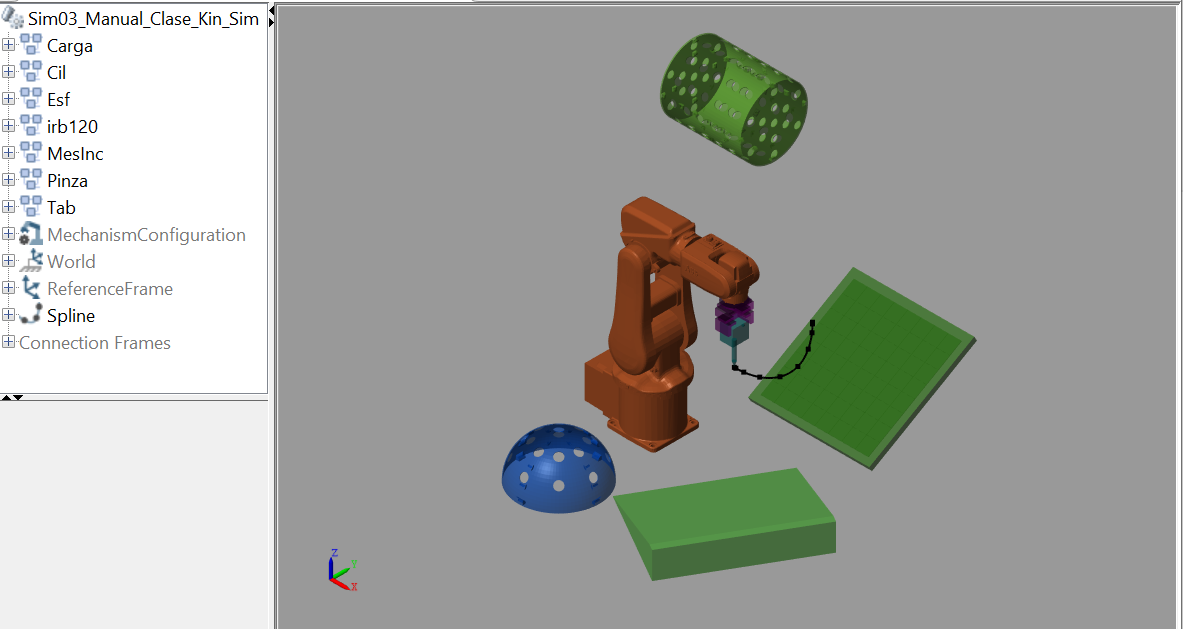

### 
$$MoveJ(pose, [Wobj], [nPts])$$


- Mueve la herramienta del robot desde la posición actual a las posiciones cartesianas *pose*.

- *pose* es una matriz ($N\times 6$) donde cada fila es la posición en la forma $[x,y,z,r_z,r_y,r_x]$.

- Si pose es solo un punto ($1\times 6$), se puede interpolar $nPts$ entre la posición actual y ese punto, por defecto $nPts=10$. 

- El robot no va en línea recta, si no por el camino más sencillo.

- Si se añade el eje de referencia $Wobj$ (objeto *Piezas*, vector *Pose* o matriz homogénea), los puntos son respecto de esa referencia.

- Si la entrada *pose* es  ($N\times 3$) se entiende que solo se da la posición $[x,y,z]$. El ángulo del robot permanece constante con el valor inicial.

### Ejemplo de $MoveJ()$: Ir a un punto con interpolación

- Ir a un punto  con referencia la base del robot.

- Ir a un punto con referencia del tablero.

rob.Rec % Resetea lo grabado
q= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(q);


punto1= [[200,0,200]*1e-3,[0,0,180]*deg];
punto2= [[100,100,0]*1e-3,[0,0,180]*deg];
% La orientación se mantiene si solo se dan las [x,y,z]
%punto1= [200,0,200]*1e-3;
%punto2= [100,100,0]*1e-3;

rob.MoveJ(punto1);
rob.MoveJ(punto2, Tab);

### El mismo movimiento con la mesa

- La mesa no está bien definida, por lo que hay que calcular su posición por tres puntos.

- Estos puntos pueden ser difíciles de hallar.

rob.Rec % Resetea lo grabado
q= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(q);

% Pesos de cada componente en la cinemática inversa
rob.W([ones(1,3),ones(1,3)]);
punto1= [[200,0,200]*1e-3,[0,0,180]*deg];
punto2= [[100,100,0]*1e-3,[0,0,180]*deg];

rob.MoveJ(punto1);
rob.MoveJ(punto2, MesInc);

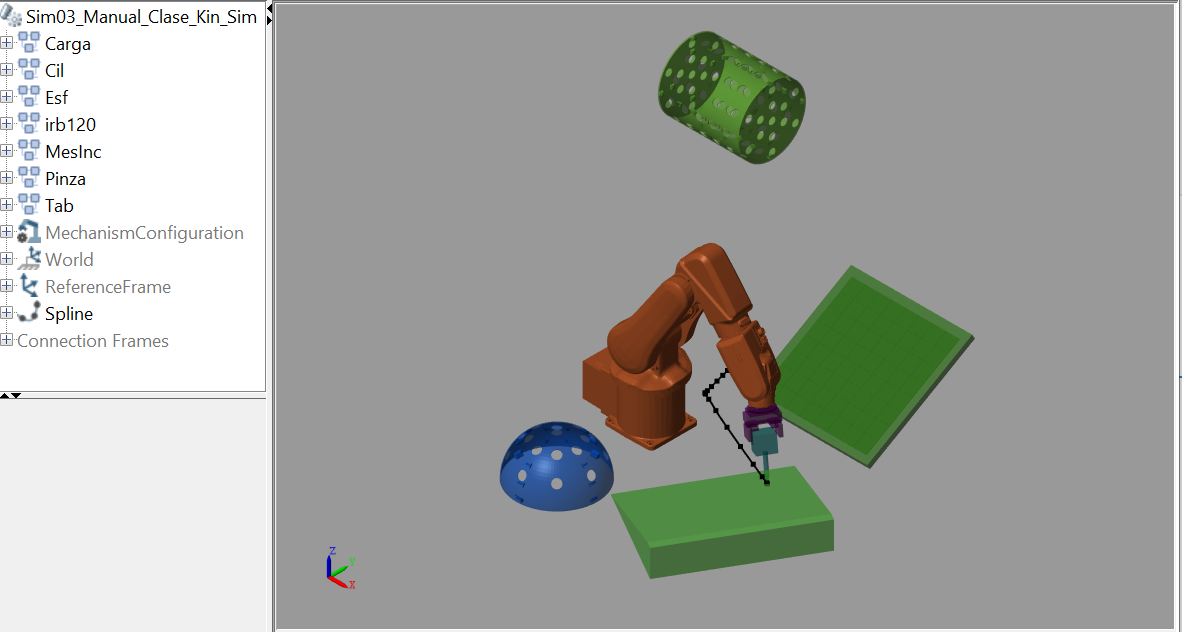                               

#### Ejemplo de $MoveJ()$: Ir a varios puntos definidos

#### Circunferencia sobre la mesa inclinada

- Conocemos los ejes de la mesa inclinada, ver apartado anterior.

- Se traza 12 puntos de una circunferencia y se mueven a la mesa. Se ven con Show() para ver si son accesibles.

- Se mueve el robot a dichos puntos.


rob.Rec % Borrar lo que se tenga
% Puntos para definir los ejes de la mesa
q= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(q);
% Puntos de la circunferencia
deg= pi/180;
nPts= 12;
theta= linspace(0, 360*deg, nPts)';
radio= 100*1e-3;
% Puntos y ángulos sobre la mesa
x= radio*cos(theta)+ 150*1e-3;
y= radio*sin(theta)+ 150*1e-3;
z= 5e-3*ones(nPts, 1);
rz= zeros(nPts, 1);
ry= zeros(nPts, 1);
rx= 180*deg*ones(nPts,1); % para poder llegar
puntos= [x,y,z,rz,ry,rx];


% Mover el robot a los puntos deseado. Se desea que los ángulos exactos
rob.MoveJ(puntos, Tab);


### El mismo movimiento en la mesa


rob.Rec % Borrar lo que se tenga

% Inicio
q= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(q);

% Puntos de la circunferencia
deg= pi/180;
nPts= 12;
theta= linspace(0, 360*deg, nPts)';
radio= 100*1e-3;
% Puntos y ángulos sobre la mesa
x= radio*cos(theta)+ 150*1e-3;
y= radio*sin(theta)+ 150*1e-3;
z= 5e-3*ones(nPts, 1);
rz= zeros(nPts, 1);
ry= zeros(nPts, 1);
rx= 180*deg*ones(nPts,1); % para poder llegar
puntos= [x,y,z,rz,ry,rx];


% Mover el robot a los puntos deseado. Se desea que los ángulos exactos
rob.MoveJ(puntos, MesInc);

% Mover al robot a los puntos deseados. No se espeficica los ángulos
% Sale igual porque se conserva los ángulos iniciales
rob.MoveJ(puntos(:,1:3), MesInc);


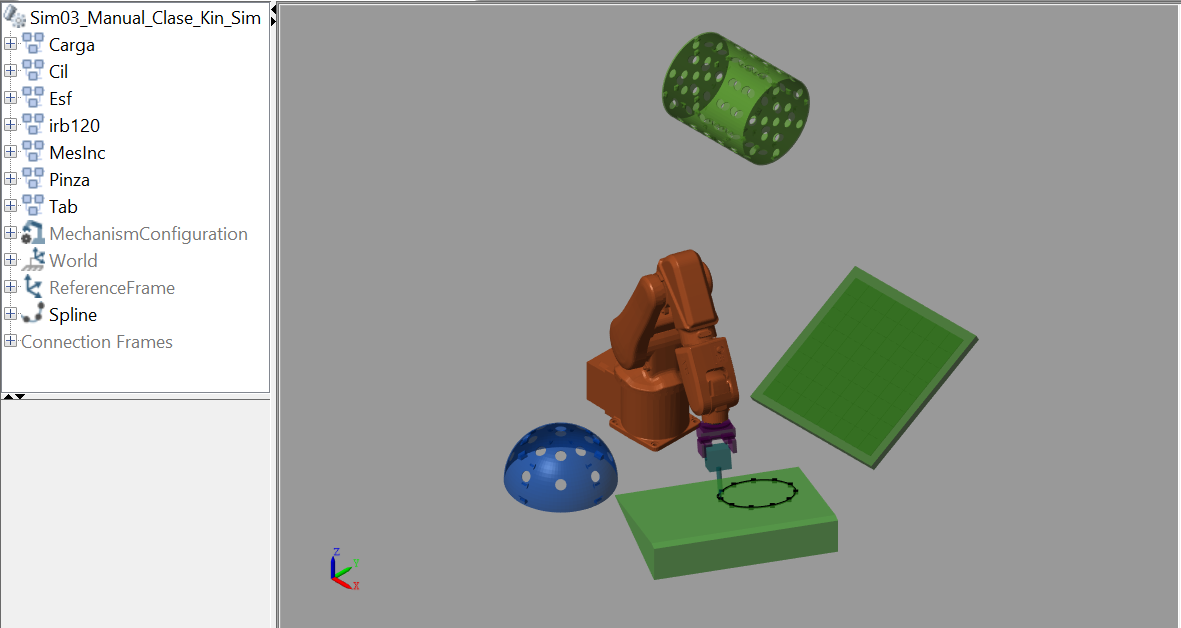

### 
$$MoveL(pose,  [Wobj], [nPts])$$


- Interpola $nPts$ desde la posición actual a la posición* pose* tipo $[x,y,z,r_z,r_y,r_x]$ en línea recta, por defecto $nPts=10$.

- Si *pose* es de tres elementos $[x,y,z]$ el ángulo es el que tiene al empezar.

- Si se incorpora los ejes del objeto de trabajo, el punto *pose* está definido con respecto a la referencia dada.

#### Ejemplo de $MoveL()$: Línea en el espacio y sobre la mesa

- La interpolación de los puntos se hace usando la librería *Robotic Toolbox *para interpolación de rotaciones y matrices homogéneas.


rob.MoveAbsJ([0,0,0,0,90,0]*deg);
puntos= [[200,300,200]*1e-3, [0,0,180]*deg];
% El objeto de trabajo es wobj0
rob.Rec
rob.MoveL(puntos);

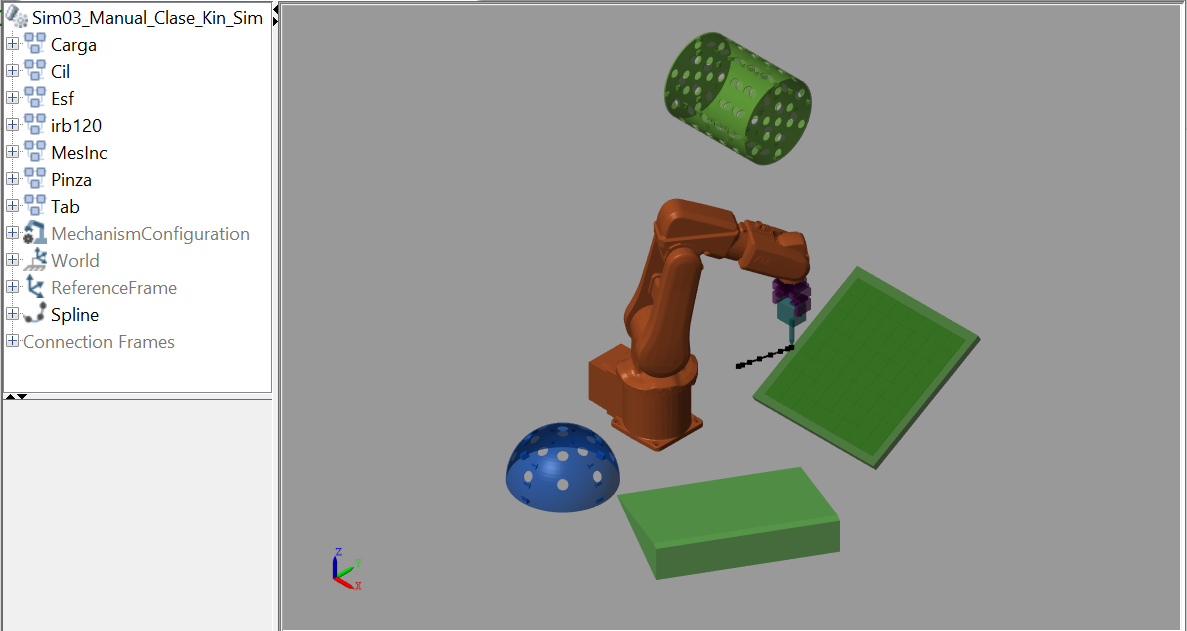

### Recta sobre el tablero y mesa

% Sobre la mesa inclinada
rob.Rec
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
puntos= [[100,100,0]*1e-3, [0,0,180]*deg];
%rob.MoveJ(puntos,Tab.Htcp);
rob.MoveJ(puntos, Tab);
puntos(1:3)= [200,200,0]*1e-3;
rob.Rec
%rob.MoveL(puntos,Tab.Htcp,10);
rob.MoveL(puntos,Tab);


 % Sobre la mesa inclinada
rob.Rec

rob.MoveAbsJ([0,0,0,0,90,0]*deg);
puntos= [[100,100,0]*1e-3,[0,0,180]*deg];
rob.MoveJ(puntos,MesInc);
puntos(1:3)= [200,200,0]*1e-3;
rob.Rec
rob.MoveL(puntos,MesInc,10);

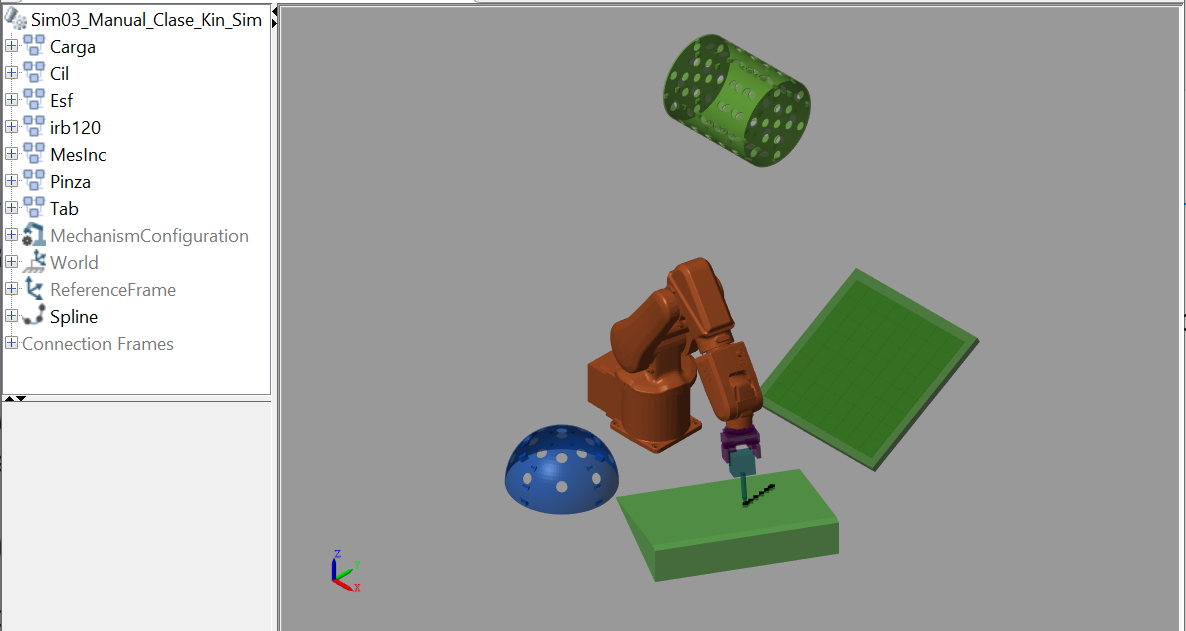

### 
$$MoveC(pos1, pos2, [Wobj], [nPts])$$


- A partir de la posición actual, el método genera un arco de semi-circunferencia que pasa por $pos1$ y llega a $pos2$. Ambos son del tipo $[x,y,z]$. El ángulo es perpendicular al plano definido por los tres puntos.

- $Wobj$ es el objeto $Piezas$, el $pose$* o* la matriz homogénea del objeto, por defecto el eje global.

- $nPts$ son los puntos deseados para la interpolación, por defecto $nPts=10$.

#### Ejemplo de $MoveC()$: Circunferencia en la mesa

- Se dibujan las 3 piezas en la mesa con posible cambio de velocidad

rob.Rec
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
punto= [[100,150,0]*1e-3,[0,0,180]*deg];
rob.MoveJ(punto,Tab.Hbase);

rob.Rec; % Se inicia grabación con reseteo
pos1= [150,200,0]*1e-3;
pos2= [200,150,0]*1e-3;
rob.MoveC(pos1,pos2,Tab);

pos1= [150,100,0]*1e-3;
pos2= [100,150,0]*1e-3;

%rob.MoveC(pos1,pos2,Tab.Htcp);
rob.MoveC(pos1, pos2, Tab);
% Se reproduce grabación completa de la circunferencia 3 veces
for i= 1:3
   rob.Rep;
   pause(3)
end


### En la mesa inclinada

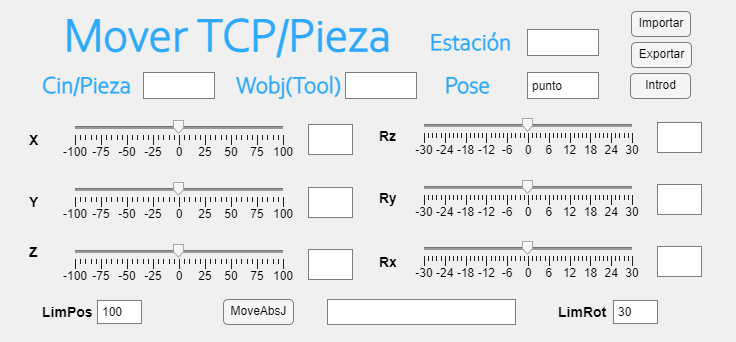

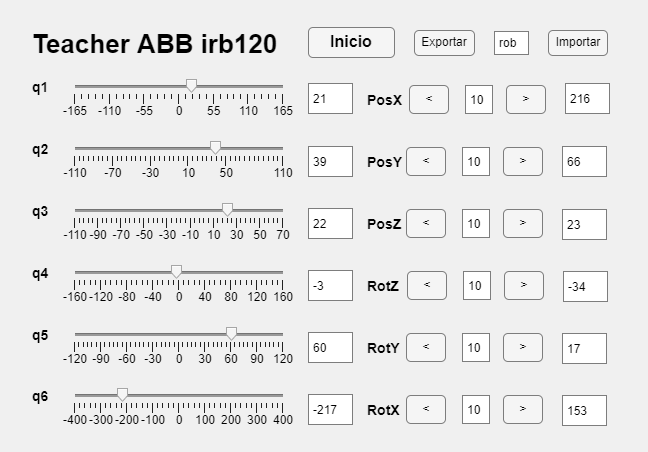

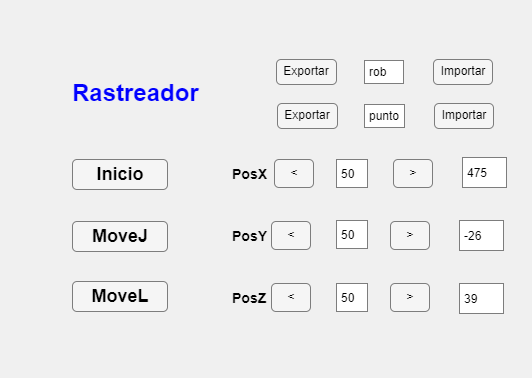


rob.Rec
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
punto= [[100,150,0]*1e-3,[0,0,180]*deg];
rob.MoveJ(punto, MesInc);

% Modificar velocidad 'V' m/s o tiempo ciclo 'T'
rob.Ts(0.1)
rob.Rec; % Se inicia grabación con reseteo
pos1= [150,200,0]*1e-3;
pos2= [200,150,0]*1e-3;
rob.MoveC(pos1,pos2,MesInc);
pos1= [150,100,0]*1e-3;
pos2= [100,150,0]*1e-3;
rob.MoveC(pos1,pos2,MesInc);

% Se reproduce grabación completa de la circunferencia 3 veces
for i= 1:3
   rob.Rep;
   pause(3)
end

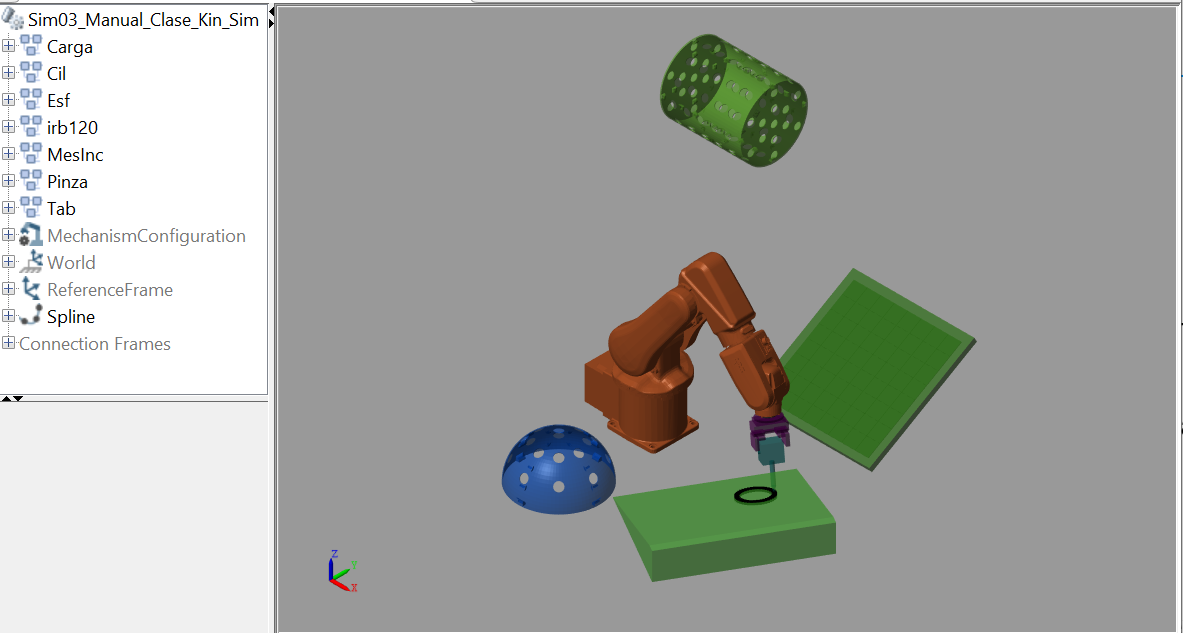

## Métodos Internos

### $Pose(joint, [Wobj])$: Cinemática directa

- Método que tiene como argumento posiciones articulares $N\times 6$ y devuelve posiciones cartesianas $N\times 6$ tipo $[x,y,z,r_z,r_y,r_x]$, correspondiente a la herramienta elegida.

- El argumento $Hwobj$ es la matriz homogénea del eje que se desea, por defecto, el eje es la base del robot.

- Sin argumentos devuelve la posición actual de la herramienta del robot.

### $Joint(pose, [w])$: Cinemática inversa

- Método que tiene como argumento posiciones cartesianas $N\times 6$ tipo $[x,y,z,r_z,r_y,r_x]$ y devuelve posiciones articulares  $N\times 6$.

- Se obtiene por cinemática inversa punto a punto.

- El vector $w=[w_{Rz},w_{Ry},w_{Rx},w_x,w_y,w_z]$ es el peso en la optimización local de las rotaciones y traslaciones

### 
$$Robot()$$


- Devuelve la propiedad robot que puede haber sido modificada.

### 
$$Sim(q, pose, t)$$


- Simula la estación que los puntos $q$ articulares, equivalentes a los $pose$ del TCP en el tiempo $t$.

## HMI (Interface hombre/máquina). Para irb120

- La interface se actualiza con los datos del objeto $Cin()$ cada vez que se le llama.

### appMover

- Mueve tanto piezas como el TCP del robot

- Su movimiento es relativo a la posición actual entre unos límites fijados

#### Elementos

- **Cin/Pieza**: Objeto** Cin** para robot o Pieza para elementos estáticos

- **Wobj(Tool)**: Objeto *Piezas o* matriz homogénea respecto a lo que se quiere mover, por defecto el eje base. Si se pone ***Tool*** es la herramienta del robot, se irá cambiando con el movimiento del mismo.

- **Pose**: Punto donde se mueve en* mm* y *Deg*. Se puede importar del sistema o exportar. 

- **Cremalleras y pantallas**: Para mover los componentes del punto. Si se usa las pantallas se debe presionar el botón introd

- **Lim**: Los límites relativos del movimiento del punto

- **MoveAbsJ y pantalla**: Visualiza la posición de ejes del robot, si se usa para robots. Se puede cambiar a mano y mover el robot. 

appMover


### appAbbIrb120

- Para el robot ABB120 únicamente.

appAbbIrb120(rob)

## HMI (Interface hombre/máquina). Movimiento por ejes cartesianos

- Puede usarse para cualquier robot porque solo se mueve por ejes cartesianos

appRastreador(rob)

## **Ejemplos**

### **Realizar un cuadrado, circunferencia y la letra B sobre la mesa inclinada**

- El rastreador interpola entre los puntos que se le da. En cada simulación se muestra todo lo guardado hasta el momento.

- Por ello es interesante no grabar al moverse a un punto aislado y solo grabar cuando se dibuja una figura concreta.

- Pese a todo, entre figuras puede haber interpolaciones no deseadas. 

% Definir el eje de la mesa por tres puntos 
% Pueden ser obtenidos con ayuda del Teacher
rob.Rec; % Borrar lo que tengamos

if 1
   Wobj= MesInc;
else
   Wobj= Tab;
end

% Ir a una posición de la mesa
x= 10; y= 100;
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
punto= [[x,y,0]*1e-3,[0,0,180]*deg];
rob.MoveJ(punto, Wobj); % Posición mesa
% Dibujar el cuadrado grabando
rob.Rec; % Inicio (resetear)
lado= 100; 
Cuadrado(rob, x, y, lado, Wobj);
rob.Rec(0); % Parar
% Dibujar circunferencia
x= 120; y= 150; radio= 50;
rob.MoveAbsJ([0,0,0,0,90,0]*deg);  % Posición Reposo
punto= [[x,y,0]*1e-3,[0,0,180]*deg];

rob.MoveJ(punto, Wobj, 10); % Posición mesa
rob.Rec(1); % Iniciar
Circunferencia(rob, x, y, radio, Wobj);
rob.Rec(0); % Parar

% Letra B
x= 230; y= 100;
rob.MoveAbsJ([0,0,0,0,90,0]*deg);  % Posición Reposo
punto= [[x,y,0]*1e-3,[0,0,180]*deg];
rob.MoveJ([[x,y,0]*1e-3, [0,0,180]*deg], Wobj);

rob.Rec(1); % Iniciar
lado= 100;
LetraB(rob, x, y, lado, Wobj);
rob.Rec(0); % Parar

% Reproducir las tres piezas
rob.Rep;


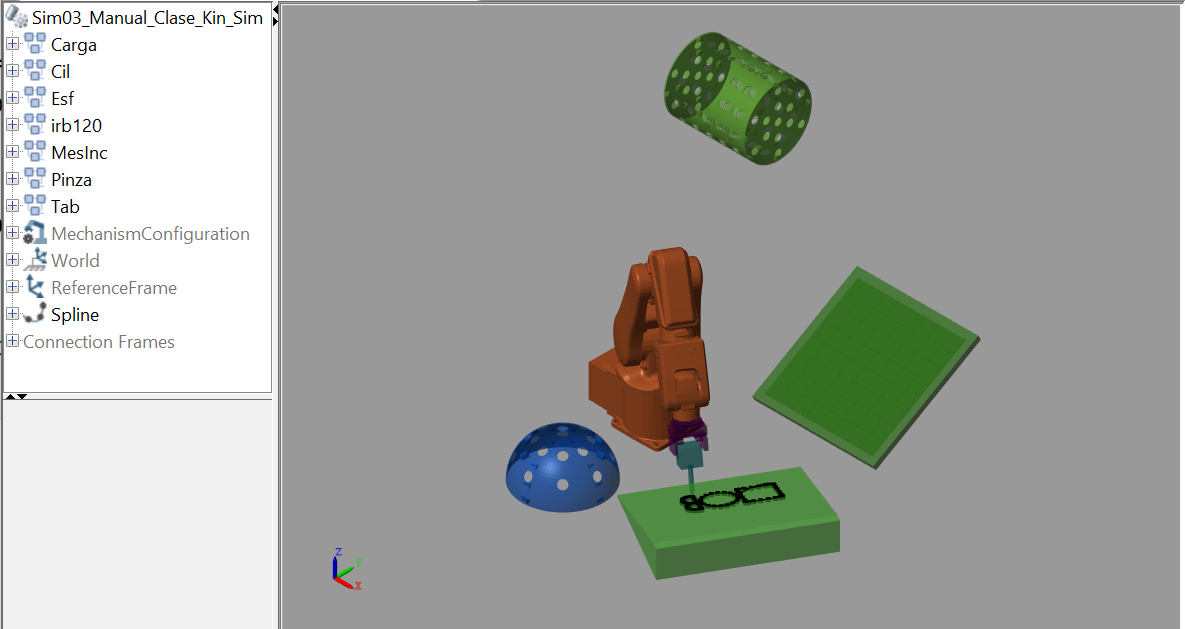

### Introducir el lápiz en alguno de los orificios de la esfera

% Eje de la esfera
% Limpiar memoria
rob.Rec;
deg= pi/180;

rz= -3; % Posiciones en z \in[-4, 4] Acimut
ry= 1; % Posiciones en y \in [0, 2] Latitud

% Definir un eje con origen en el centro de la esfera y eje z con ángulo
% del orificio deseado
%eje= [[0,-350,0]*1e-3,[45*rz,30*ry,0]*deg];
% Se define un eje en la posición de la esfera girado

% Se modifica el eje de la esfera
eje= Prod(Esf,[[0,0,0],[0*rz,30*ry,0]*deg]);

ans =   Simulink.SimulationOutput:

                   tout: [108x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


% Puntos respecto del eje modificado
pose1= [[0,0,200]*1e-3,[0,0,180]*deg];
pose2= [[0,0,100]*1e-3,[0,0,180]*deg];
% Ir al los puntos y volver
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(pose1, eje);
rob.MoveJ(pose2,eje);
rob.MoveJ(pose1,eje);
rob.MoveAbsJ([0,0,0,0,90,0]*deg);

r1 = struct with fields:
        Carga: [1×1 Pieza]
        Pinza: [1×1 Pieza]
     TcpCarga: 'Body10'
     TcpPinza: 'Body09'
    baseRobot: [0 0 0 0 0 0]
           q0: [0 0 0 0 0 0]
        robot: [1×1 rigidBodyTree]


Herramienta: Body10


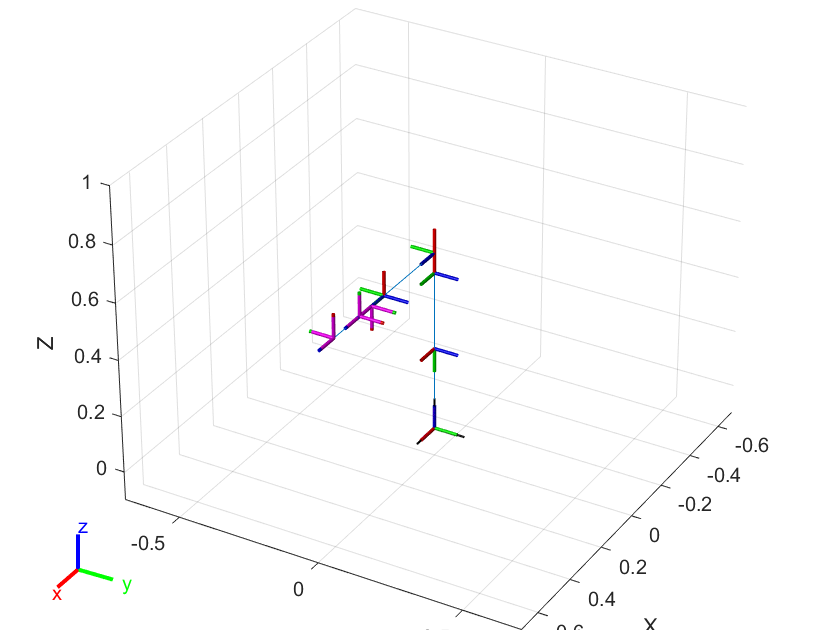


eje= Prod(Esf,[[0,0,0],[45*rz,30*ry,0]*deg]);


pose1= [[0,0,200]*1e-3,[0,0,180]*deg];
pose2= [[0,0,100]*1e-3,[0,0,180]*deg];

ans =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body01'  'Body02'  'Body03'  'Body04'  'Body05'  'Body06'  'Body07'  'Body08'  'Body09'  'Body10'}
      BaseName: 'Base'
       Gravity: [0 0 -9.8066]
    DataFormat: 'column'


rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(pose1, eje);

rob.MoveJ(pose2,eje);

rob.MoveJ(pose1,eje);
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
% Repetir movimiento

JacIK activado

 rob.Rep

Unable to resolve the name 'robPalo.MoveJ'.

H = se3
    1.0000         0         0    0.1000
         0   -1.0000   -0.0000    0.1000
         0    0.0000   -1.0000         0
         0         0         0    1.0000


                                  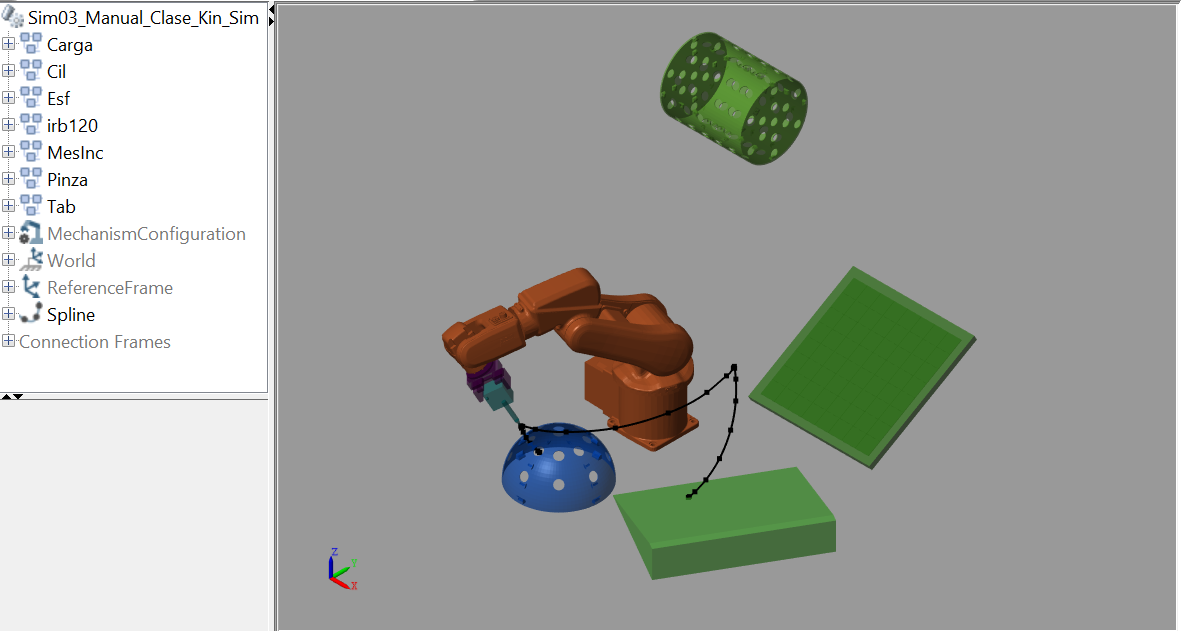

# Ejercicios propuestos:

- Dibujar sobre la mesa inclinada diferentes objetos, circunferencias, triángulos y otra serie de figuras y letras.

- Introducir la herramienta lápiz en orificios aleatorios de la esfera y el cilindro.

- Cambiar la herramienta a *barra20* y repetir el punto anterior

## Apéndice: Objeto $Cin()$ RigidBody

- La librería *Robotic Toolbox* genera un objeto multibody que va a ser el encargado de obtener las cinemáticas inversas. 

- El objeto funciona en Matlab y puede ser representado por sus ejes, o con ayuda de los ficheros *.stl. Esta segunda opción no es obvia ya que hay que saber la posición de los ficheros respecto de los ejes.

r1= load('Rob_irb120_DH.mat')

robPalo= Cin(r1.robot, [], r1.TcpCarga, q0);


rob.Hbody([[100,100,0]*1e-3,[0,0,0]*deg])


### Movimiento con el objeto *MultiBody*

q= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ(q);


punto1= [[200,0,200]*1e-3,[0,0,180]*deg];
punto2= [[100,100,0]*1e-3,[0,0,180]*deg];

robPalo.MoveJ(punto1);
robPalo.MoveJ(punto2, Tab.Hbase);


pose= [[100,100,0]*1e-3,[0,0,180]*deg];

H= se3(pose(1, 4:6), 'eul', pose(1, 1:3))



### Funciones definidas para el ejemplo

function Cuadrado(rob, x, y, lado, Wobj)
    deg= pi/180;
    nPts= 10;
    pose= [[x+lado,y,0]*1e-3, [0,0,180]*deg];
    rob.MoveL(pose, Wobj, nPts);
    pose(1:3)= [x+lado,y+lado,0]*1e-3; 
    rob.MoveL(pose, Wobj);
    pose(1:3)= [x,y+lado,0]*1e-3; 
    rob.MoveL(pose, Wobj);
    pose(1:3)= [x,y,0]*1e-3; 
    rob.MoveL(pose, Wobj);
end

function Circunferencia(rob, x, y, radio, Wobj)
   nPts= 10;
   pos1= [x+radio,y+radio,0]*1e-3;
   pos2= [x+2*radio,y,0]*1e-3;
   rob.MoveC(pos1, pos2, Wobj, nPts);
   pos1= [x+radio,y-radio,0]*1e-3;
   pos2= [x,y,0]*1e-3;
   rob.MoveC(pos1, pos2, Wobj, nPts);
end

function LetraB(rob, x, y, lado, Wobj)
   deg= pi/180;
   %rob.MoveJ([[x,y,0]*1e-3, [0,0,180]*deg],Wobj);
   rob.MoveL([[x,y+lado,0]*1e-3,[0,0,180]*deg], Wobj);
   rob.MoveC([x+lado/3,y+3*lado/4,0]*1e-3,[x,y+lado/2,0]*1e-3, Wobj);
   rob.MoveC([x+lado/3,y+lado/4,0]*1e-3,[x,y,0]*1e-3, Wobj);
end